## Factorio Math

Jaiden King

1/31/2025

clear all
close all
clc

Here we are trying to model our production from the game Factorio. The game has many resources and many production recipes, but we will be limiting ourselves to basic Electronic Circuit assembling machines because they form a simple 2:3 ratio with Copper Cable assembling machines which will be easy to verify while being complex enough to know we're doing math. 

In this example, we will model the two types of assembling machines shown below and calculate the number of each machine type we need for a desired circuit production value. 

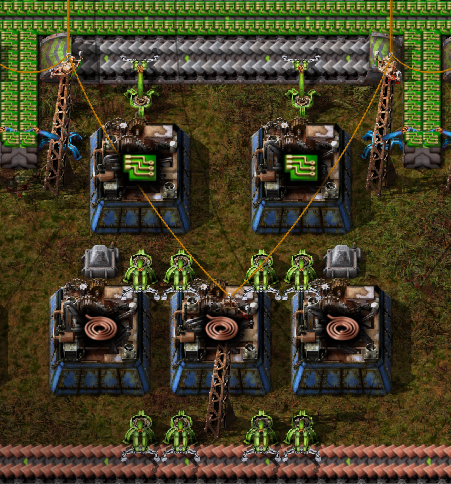

Each recipe in the game has 2 key properties: A list of ingredients and a crafting time. 

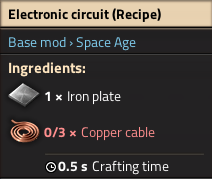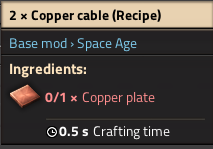

Each recipe can be represented as a column vector whos entries represent the change in some resource per unit time. To construct the vectors we can copy the values from the in-game recipe and divide by the crafting time for that recipe.

Our row order will be: copper plate, iron plate, copper cable, circuits.

All rows for all recipes must be populated and a 0 can be used if the item doesn't appear in the recipe. Negative values represent an item being consumed and positive values are items produced.

circuit_recipe = [0 -1 -3 1]'/0.5

circuit_recipe =      0
    -2
    -6
     2


cable_recipe = [-1 0 2 0]'/0.5

cable_recipe =     -2
     0
     4
     0


To make the math more consie we will name the circuit recipe $\bf a_1$ and the cable recipe $\bf a_2$. If we define $x_1$to be the number of circuit assembly machines and $x_2$ to be the number of cable assembly machines, then we can use the expression $x_1 {\bf a_1} + x_2{\bf a_2}$ to compute the total change of resources per unit time of the system. We can combine $\bf a_1$and $\bf a_2$ into a single matrix $A = [{\bf a_1\ a_2]$ and write the system expression as $A{\bf x} = {\bf y}$ where ${\bf x} = [x_1\ x_2]^T
$ is a column vector defining the number of each type of machine and ${\bf y} = [y_1\ y_2\ y_3\ y_4]^T$ is the production rates of each resource.

Suppose we want to find the number of machines required to balance the cable consumption and production ($y_3 = 0$) while achieving some circuit production value ($y_4 = 4$). That means we are interested in finding a value of $\bf x$ such that $A{\bf x}=[y_1\ y_2\ 0\ 4]^T$.

y = [0 0 0 4]';
A = [circuit_recipe cable_recipe]

A =      0    -2
    -2     0
    -6     4
     2     0


Our strategy will be to augment the array and reduce the equation to reduce row echelon form.

augmented = [A y]

augmented =      0    -2     0
    -2     0     0
    -6     4     0
     2     0     4


% I'm going to do what's called a pro gamer move.
% Simply delete the rows we're not interested in.
augmented = augmented(3:4,:)

augmented =     -6     4     0
     2     0     4


reduced = rref(augmented)

reduced =      1     0     2
     0     1     3


x = reduced(:,end)

x =      2
     3


Here's an alternative method to find $\bf x$ that leverages more of Matlab's built-in functions. We extract just the rows for the resources we're interested in constraining and use `mldivide` to solve for $\bf x$

rows = [3 4];
A_ = A(rows,:)

A_ =     -6     4
     2     0


y_ = y(rows)

y_ =      0
     4


x = A_\y_

x =      2
     3


Thus we have found a value for $\bf x$ that balances cable production and produces the desired number of circuits. We might now be interested in seeing the effects this has on the other resources:

y = A*x

y =     -6
    -4
     0
     4


In this result we see $y_1 = -6$ and $y_2 = -4$ indicating that 6 copper plates and 4 iron plates are consumed by this system.

This math relied on simply removing the rows we were not interested in constraining during the row reduction process. I don't know if this is mathematically valid or if we just got lucky. 

This technique should be extendable to more machine types and larger systems.